% Fractional order proportional derivative controller discretization
% Contact: Bo Shang
% cnpcshangbo@gmail.com

## Impulse response invariant discretization of fractional order

## integrators/differentiators

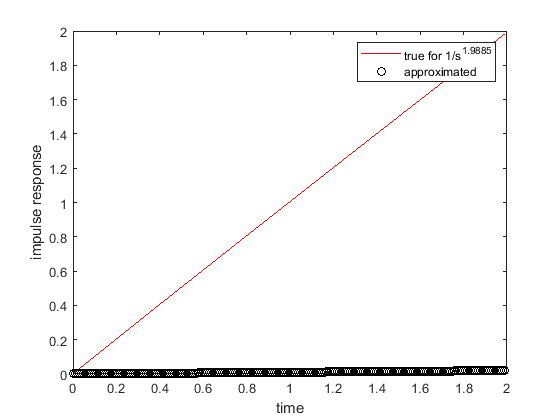

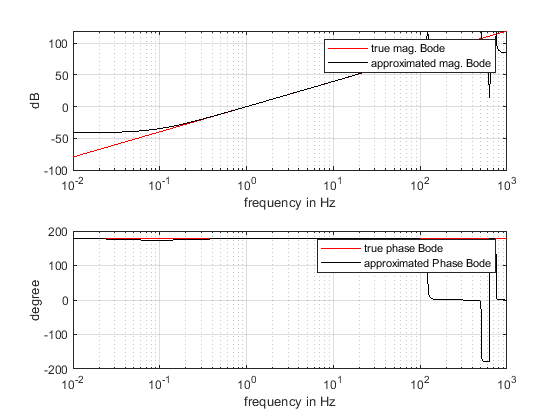

gam=0.9885+1;
Ts=.01;
dfod=irid_fod(gam,Ts,5); % Try this method

## FOPD

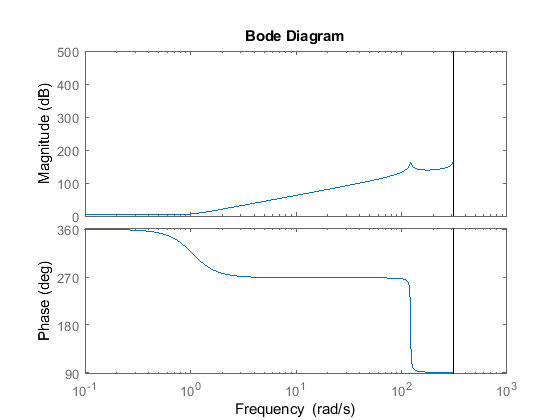

kp=1.5489;
ki=0.8829;
s=tf('s');

cd=kp*(1+ki*c2d(s,Ts,'tustin')*dfod);
figure
bode(cd)


K=0.8592; T1=1.0710;
p=K/(T1*s+1)/s;
pd=c2d(p,Ts,'matched');%plant

phiz=cd*pd/(1+cd*pd);% this is to calculate the poles
% this link show how poles determines the vibration: http://www.dcsc.tudelft.nl/~sc4060/transp/discreteNOTES.pdf